
i=4;
%v=T2{i,3:7};
%v=T{i,2:6};
%v=T3{i,8:12};
%v=reasonable{i,8:12};
%v=T_err{i,6:10};
v=T_err_bs20{i,6:10};
%v=T_calcr{i,6:10};
%v=T_err_topNTD{i,6:10};
%v=abs(params_FHOD);
%v=FHOD_T{i,2:6};
%v=Capu_T{i,2:6};
%v=Capu_T_reas{i,2:6};
%v=T_noF3D37{i,6:10};
v=num2cell(v);
[v1,v2,v3,v4,v5]=v{:};

% the gating factors scale k_pab (delivery)
Capu_gating=1; % from (Zweifel & Courtemanche, 2020)
FHOD_gating=0.2; % cannot find specifically for fhodB but FHOD is listed as 0.2 in (Zweifel & Courtemanche, 2020)
bni1_gating=0.5; % from (Zweifel & Courtemanche, 2020)

vals=ones(1,5);
vals(1)=5*10^(1); %k_paf

vals(2)=4*10^(-1.9); % k_pab

vals(3)=1*10^(5.1); %k_paf_rev

vals(4)=8*10^(10); %r_PF_rev

vals(5)=2*10^(9); %r_paf_rev

% vals(1)=26; %k_paf
% 
% vals(2)=5; % k_pab
% 
% vals(3)=20000; %k_paf_rev
% 
% vals(4)=600; %r_PF_rev
% 
% vals(5)=75000; %r_paf_rev

%num2cell(vals(:)./min(vals))'
vals=num2cell(vals);

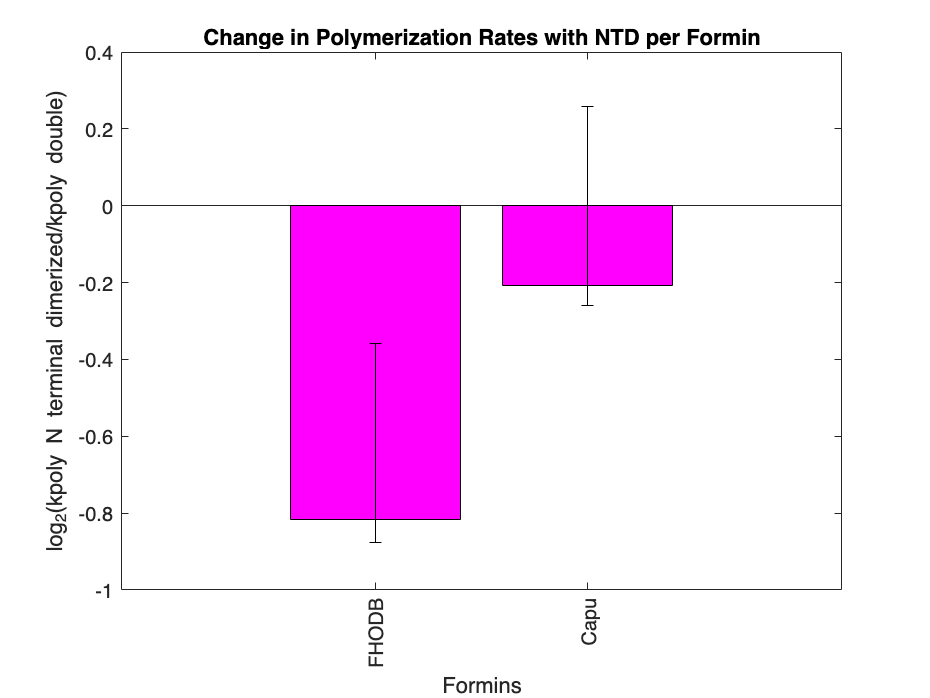


% x=[...
%         (log2(FHOD.kdim(vals{:})./(FHOD.kdob(vals{:})))),...
%         (log2(Capu.kdim(vals{:})./(Capu.kdob(vals{:}))))...
%     ];
% x=[...
%         (log2(FHOD.kdimc(vals{:})./(FHOD.kdobc(vals{:})))),...
%         (log2(Capu.kdimc(vals{:})./(Capu.kdobc(vals{:}))))...
%     ];
% x=[...
%         (log2(FHODbs20.kdim(vals{:})./(FHODbs20.kdob(vals{:})))),...
%         (log2(Capubs20.kdim(vals{:})./(Capubs20.kdob(vals{:}))))...
%     ];

% x=[...
%         (log2(FHODbs20.kdim(vals{1},vals{2}*.6,vals{3},vals{4},vals{5})./(FHODbs20.kdob(vals{:})))),...
%         (log2(Capubs20.kdim(vals{1},vals{2}*.6,vals{3},vals{4},vals{5})./(Capubs20.kdob(vals{:}))))...
%     ];

% x=[...
%         (log2(FHODbs35.kdim(vals{:})./(FHODbs35.kdob(vals{:})))),...
%         (log2(Capubs35.kdim(vals{:})./(Capubs35.kdob(vals{:}))))...
%     ];

x=[...
        (log2(FHODbs35.kdim(vals{1},vals{2}*FHOD_gating,vals{3},vals{4},vals{5})./(FHODbs35.kdob(vals{1},vals{2}*FHOD_gating,vals{3},vals{4},vals{5})))),...
        (log2(Capubs35.kdim(vals{1},vals{2}*Capu_gating,vals{3},vals{4},vals{5})./(Capubs35.kdob(vals{1},vals{2}*Capu_gating,vals{3},vals{4},vals{5}))))...
    ];

y={FHOD.name; Capu.name};
kpoly_table_ratio = table(x', 'RowNames', y);
kpoly_bar_ratio = bar(kpoly_table_ratio{:,:});
hold on
set(gca,'xtick',1:2, 'xticklabel',kpoly_table_ratio.Properties.RowNames)
xtickangle(90)
set(kpoly_bar_ratio(1), 'FaceColor','m')
errlow=[-0.2584555583 -0.2584555583];
errhigh=[0.2584555583 0.2584555583];
er = errorbar([1 2],[-0.6172640408 0], errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';
xlabel('Formins')
ylabel('log_2(kpoly N terminal dimerized/kpoly double)')

%ylim([-0.62 0.3])
%ylim([-0.05 0.1])

hold off
title('Change in Polymerization Rates with NTD per Formin')

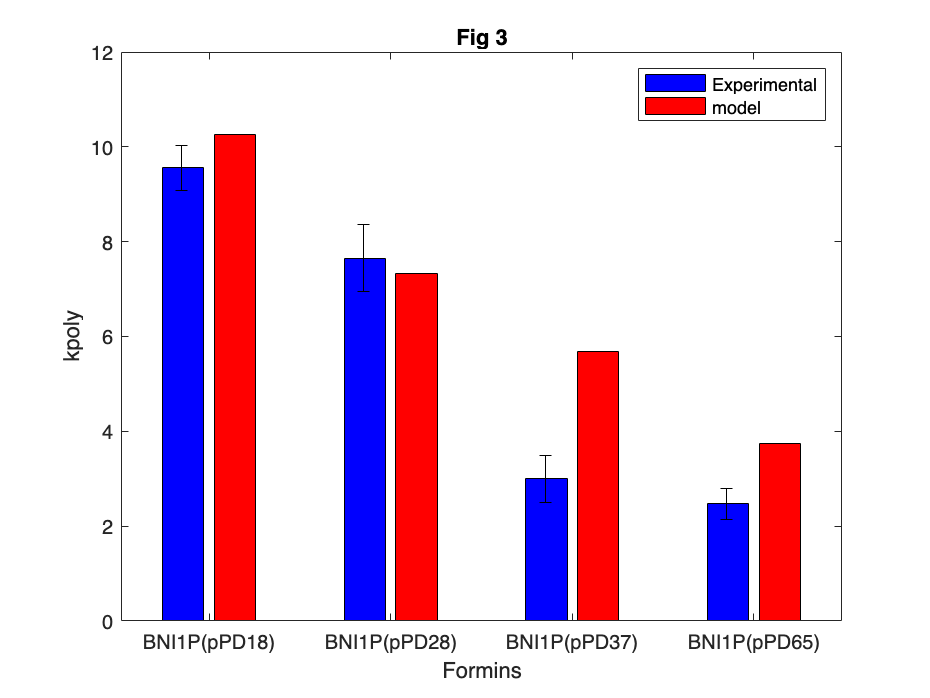

%kpolybar=bar([fig3k',fig3ksimf(vals{:})]);
%kpolybar=bar([fig3k',fig3ksimfc(vals{:})]);
kpolybar=bar([fig3k',fig3ksimf_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);

set(gca,'xticklabel',{fig3sim.name});
hold on

er = errorbar([0.85 1.85 2.85 3.85],fig3k', fig3_err_bot,fig3_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

    set(kpolybar(1), 'FaceColor','b');
    set(kpolybar(2), 'FaceColor','r');
    legend( 'Experimental', 'model');
    xlabel('Formins');
    ylabel('kpoly');
    title("Fig 3")
    hold off

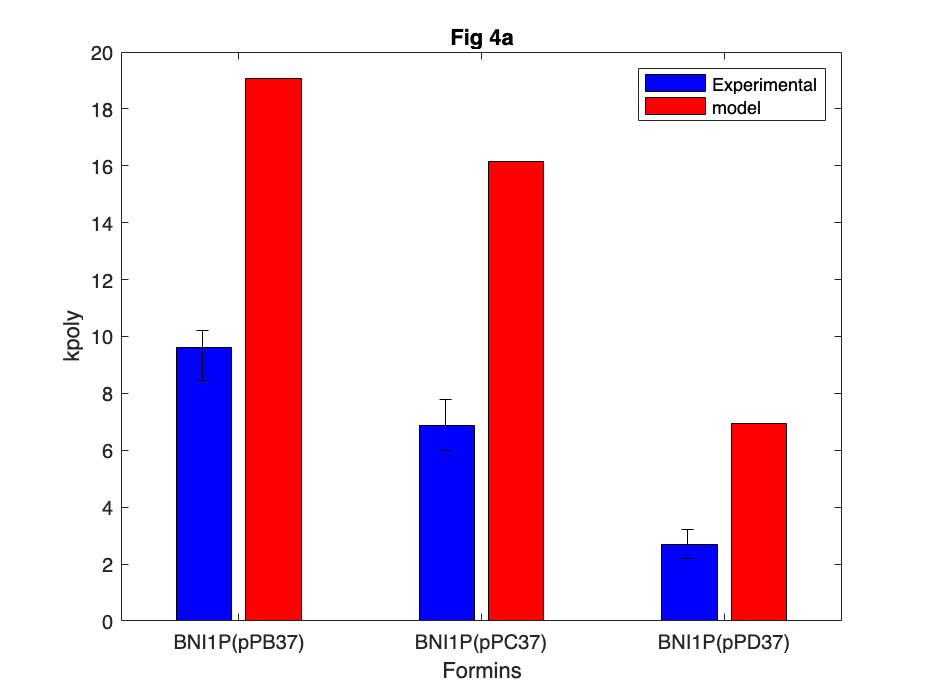

%kpolybar=bar([fig4ak',fig4aksimf(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimfc(vals{:})]);
%kpolybar=bar([fig4ak',fig4aksimf_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);
kpolybar=bar([fig4ak',fig4aksimf(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);


set(gca,'xticklabel',{fig4asim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ak', fig4_err_bot,fig4_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4a")
hold off

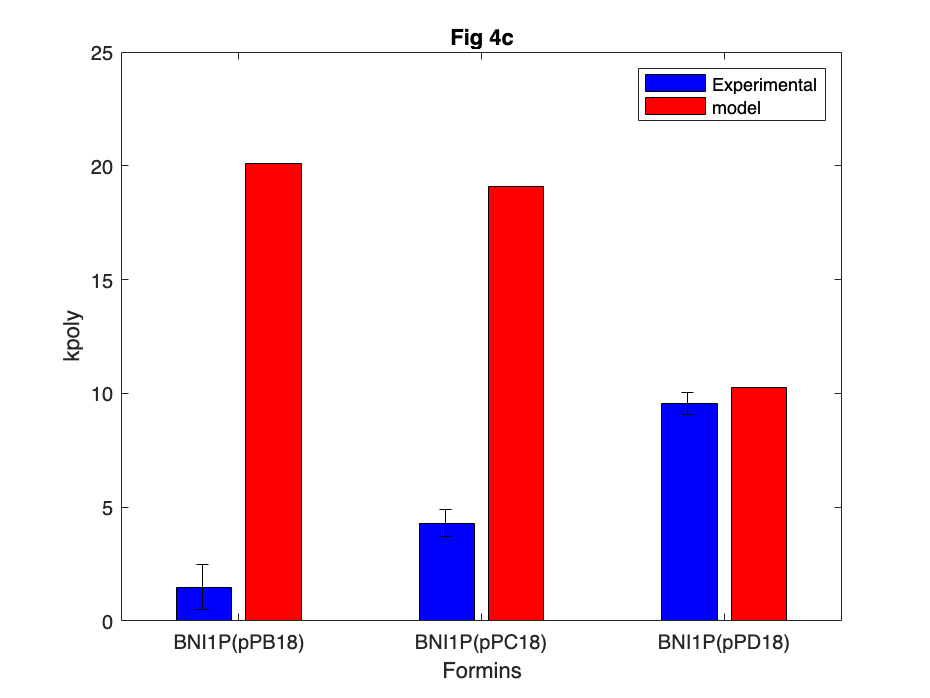

%kpolybar=bar([fig4ck',fig4cksimf(vals{:})]);
%kpolybar=bar([fig4ck',fig4cksimfc(vals{:})]);
kpolybar=bar([fig4ck',fig4cksimf_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);


set(gca,'xticklabel',{fig4csim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ck', fig4c_err_bot,fig4c_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4c")
hold off

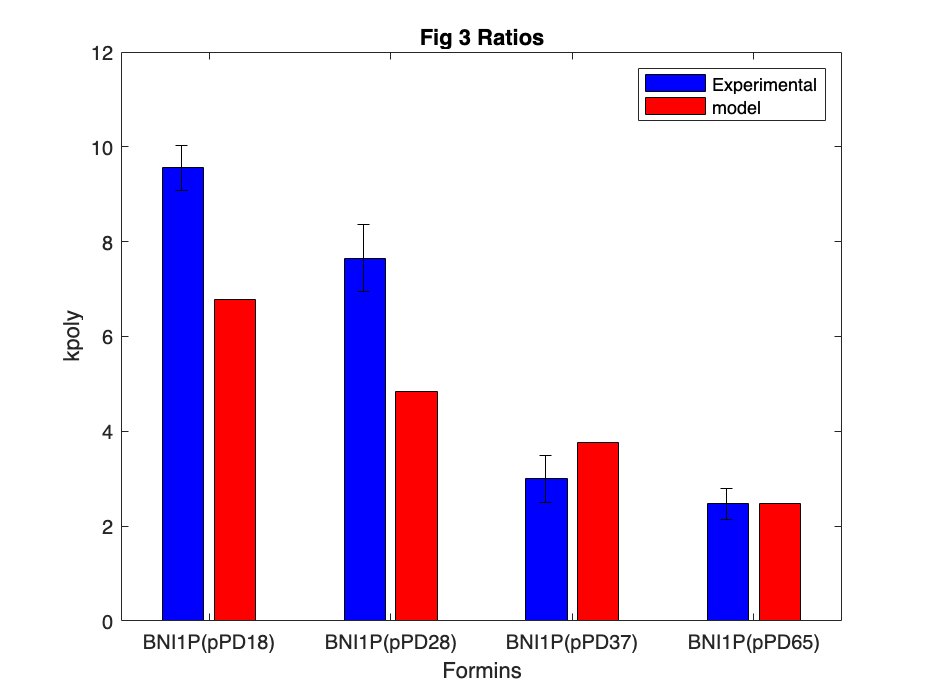


kpolybar=bar([fig3k',fig3ksimf_r_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);

set(gca,'xticklabel',{fig3sim.name});
hold on

er = errorbar([0.85 1.85 2.85 3.85],fig3k', fig3_err_bot,fig3_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

    set(kpolybar(1), 'FaceColor','b');
    set(kpolybar(2), 'FaceColor','r');
    legend( 'Experimental', 'model');
    xlabel('Formins');
    ylabel('kpoly');
    title("Fig 3 Ratios")
    hold off

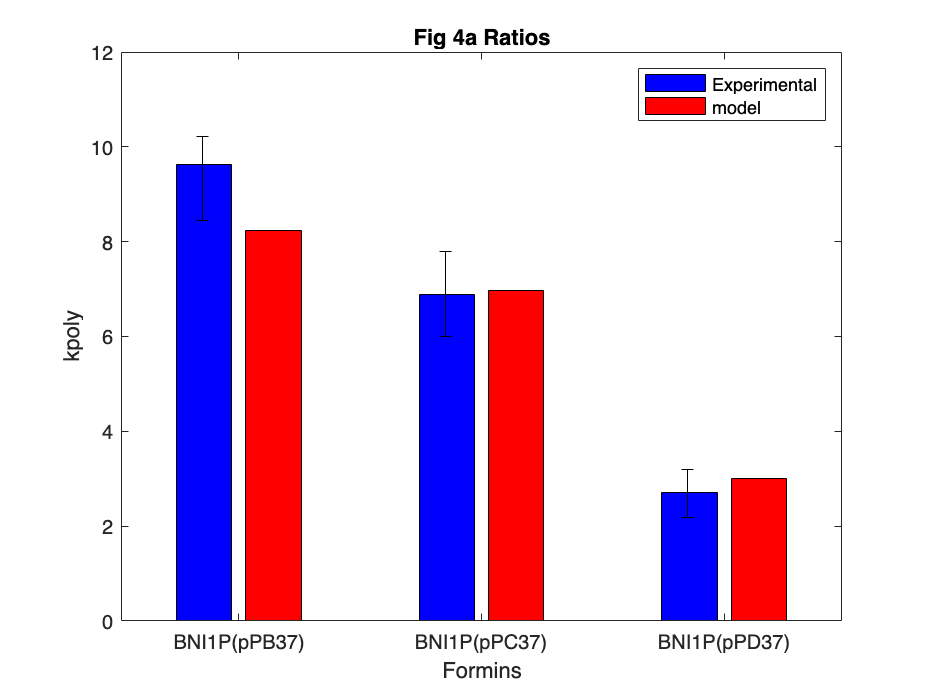

%kpolybar=bar([fig4ak',fig4aksimf_r_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);
kpolybar=bar([fig4ak',fig4aksimf_r(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);


set(gca,'xticklabel',{fig4asim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ak', fig4_err_bot,fig4_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4a Ratios")
hold off

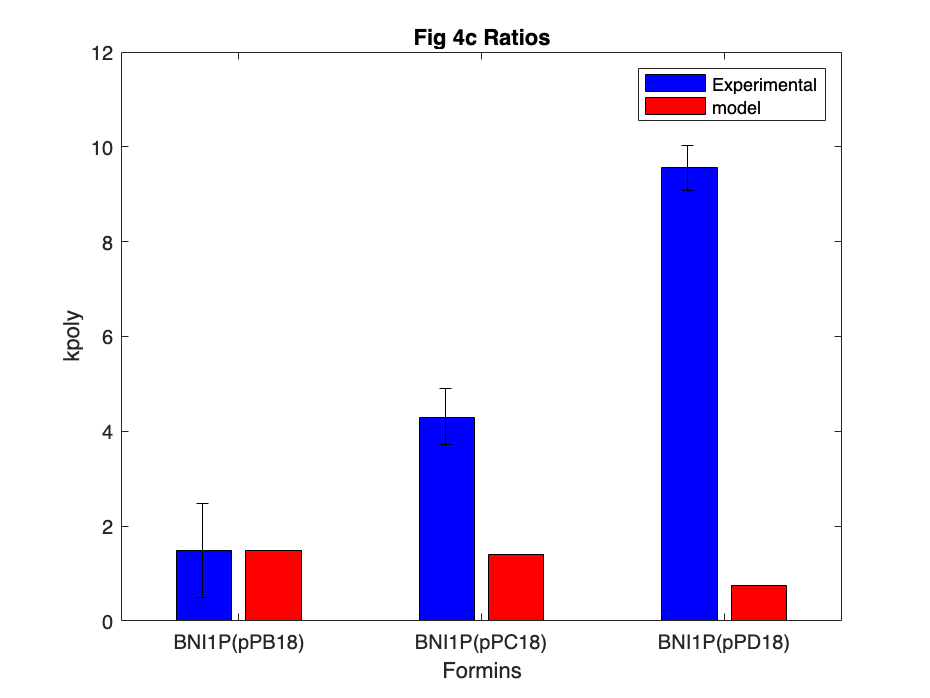

kpolybar=bar([fig4ck',fig4cksimf_r_bs20(vals{1},vals{2}*bni1_gating,vals{3},vals{4},vals{5})]);


set(gca,'xticklabel',{fig4csim.name});
hold on

er = errorbar([0.85 1.85 2.85],fig4ck', fig4c_err_bot,fig4c_err_top);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';

set(kpolybar(1), 'FaceColor','b');
set(kpolybar(2), 'FaceColor','r');
legend( 'Experimental', 'model');
xlabel('Formins');
ylabel('kpoly');
title("Fig 4c Ratios")
hold off